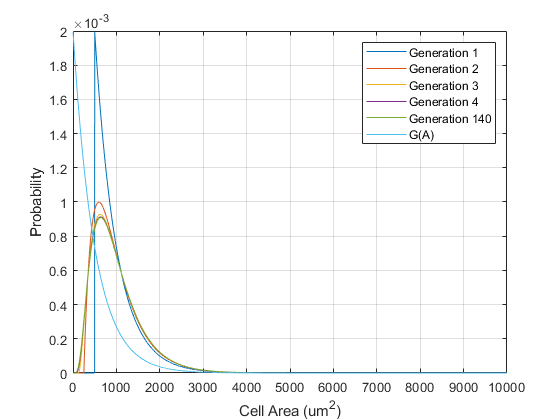

clc
clear

%%%%% Model Algorithm Demonstration %%%%%


%%%%% Initialise the mass gain function and Area distribution
%%%%% Area Dist is a delta function about 500 here

i = 1;
L = 0.002;
while i < 10001  
    if i == 500
    A(i) = 1;
    else
    A(i) = 0;
    end
         G(i) = L*exp(-L*i);
    i = i + 1;
end


%%%%% Begin the Iterative Process

i = 1;
while i < 150
    
    %%%% Random Area variable addded to random gain variable 
    %%%% Convolution Theorem means that we may multiply in
    %%%% Fourier space
    
    A = ifft(fft(G(:)).*fft(A(:)));
    store(:,i) = A;
    i2 = 1;
    counter = 1;
    
    %%%% Conduct the transform F(A) --> F(2A) to simulate division
    %%%% 5000 is an arbitrary value to cut this off at, simply chosen
    %%%% as the area values for this 'L' do not exceed it
    while i2 < 5001
        
        A(i2) = A(counter+1)+A(counter);
        counter = counter + 2;
        i2 = i2 + 1;
    end
    
    %%%% Correct for any losses in the transformation
    A(5000:10000) = 0;
    sumo = sum(A);
    A = A/sumo;
    i = i + 1;
end



%%%% Show the result

figure
plot(store(:,1)); hold on
plot(store(:,2)); 
plot(store(:,3)); 
plot(store(:,4));
plot(store(:,140));
plot(G); hold off
xlabel('Cell Area (um^2)')
ylabel('Probability')
legend('Generation 1','Generation 2','Generation 3','Generation 4','Generation 140','G(A)')
grid on

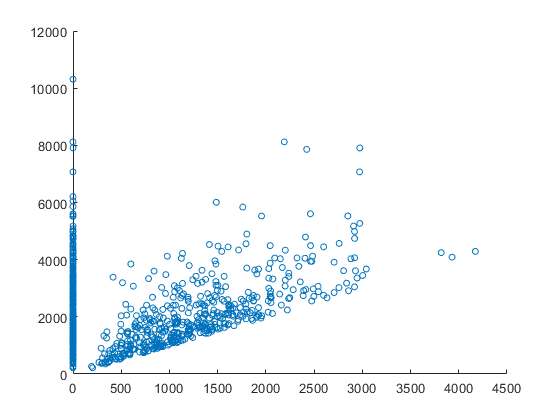

Unrecognized function or variable 'average_line'.

clc
clear

%%%% Stochastic Simulation %%%%

%%%% set initial parameter values %%%%
alpha = 0.35/350000;
k = 2/1000;
Cell_matrix = zeros(1000,4);
Cell_matrix(1,:) = [350,700,350,350];

%%%% Run iteration, one initial cell %%%% 
Cell_count = 1;
while Cell_count < 1001
    
    i = 1;
    while i < Cell_count + 1
        
        %%%% Grow the cells, growth rate proportional to division size
        Cell_matrix(i,1) =  Cell_matrix(i,1) + k*Cell_matrix(i,2);
        r = rand();
        %%%% Division Probability at all 't' proportional to division size
        P = alpha*Cell_matrix(i,2);
        %%%% Check if the cell has divided
        %%%% If yes update birth size, division size, prior birth size etc.
        if r < P
            Cell_matrix(i,2) = Cell_matrix(i,1);
            
            Cell_matrix(Cell_count+1,1) = (Cell_matrix(i,1)/2);
            Cell_matrix(Cell_count+1,2) = Cell_matrix(i,1);
            Cell_matrix(i,4) = Cell_matrix(i,3);
            Cell_matrix(Cell_count+1,4) = Cell_matrix(Cell_count+1,3);
            Cell_matrix(i,3) = (Cell_matrix(i,1)/2);
            Cell_matrix(Cell_count+1,3) = (Cell_matrix(i,1)/2);          
            Cell_matrix(i,1) = (Cell_matrix(i,1)/2);
            Cell_count = Cell_count + 1;
        end
        
        i = i + 1;
        
    end
    
   %%%% Iterate until a desired cell count is reached
end
Cell_Store(:,:) = Cell_matrix(1:1000,:);

%%% demonstration of the adder behaviour of the model 
figure
scatter(Cell_Store(:,4,1),Cell_Store(:,2,1),20); hold on

xlabel('Birth Size (a.u)')
ylabel('Division Size (a.u)')
grid on

%%%% Current area distribution may be fitted to experimental data
%%%% by minimising the KBL Divergance across alpha values

clc
clear

%%%% Demonstration of stability for the area distribution mean 

%%%% set initial parameter values %%%%
i = 1;
a= 1/350000;
k = 0.5/1000;
count = 1;
Ad = 350;
%%%% Adjust is  when the division area will be disturbed %%%%
adjust = [10,30,50,70,0];


while i < 101
    
    %%%% Mean proliferation time %%%%%
    tm = -1/(log(1-a*Ad));
    %%%% Growth Rate
    B = k*Ad;
    %%%% Expected gain in area
    Adiv(i) = (1/2)*Ad - B/(log(1-a*Ad));
    Ad = Adiv(i);
    tmd(i) = tm;
    if i == adjust(count)
        Ad = Ad + 300*(rand()-0.5);
        count = count + 1
        i
    end
    
    i = i + 1;
end

count = 2

i = 10

count = 3

i = 30

count = 4

i = 50

count = 5

i = 70


%%%%% As above but we have doubled alpha 
i = 1;
a= 2/350000;
k = 0.5/1000;
count = 1;
Ad = 175;
adjust = [10,30,50,70,0];


while i < 101
    
    tm = -1/(log(1-a*Ad));
    B = k*Ad;
    Adiv2(i) = (1/2)*Ad - B/(log(1-a*Ad));
    Ad = Adiv2(i);
    tmd2(i) = tm;
    if i == adjust(count)
        Ad = Ad + 300*(rand()-0.5);
        count = count + 1
        i
    end
    
    i = i + 1;
end

count = 2

i = 10

count = 3

i = 30

count = 4

i = 50

count = 5

i = 70

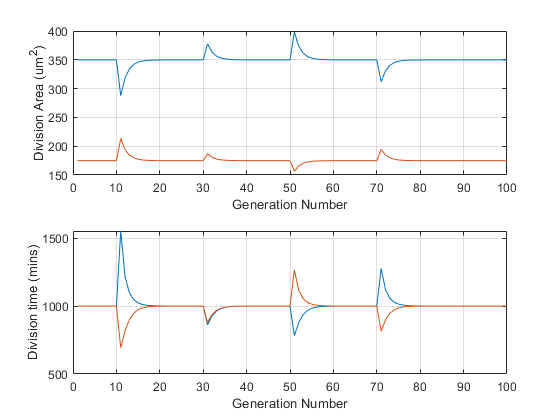


figure
%%%% Mean area stable to perturbation in Ad but not alpha
subplot(2,2,1:2)
plot(Adiv); hold on
plot(Adiv2); hold off
xlabel('Generation Number')
ylabel('Division Area (um^2)')
grid on
subplot(2,2,3:4)
%%%% Proliferation rate stable to both
plot(tmd); hold on
plot(tmd2); hold off
xlabel('Generation Number')
ylabel('Division time (mins)')
grid on